# Sliding mode control

- Simple example (https://www.youtube.com/watch?v=_NTMkXdbX6o) 

Consider 

           ${\dot{x} }_1 =x_{2\;} ,{\dot{\;x} }_2 =u+f\;,\;f:\textrm{unknown}\;\textrm{disturbance}$,  (1)

Design $u$ the trajectories converge to zero 

1. Without disturbace 

             
$$u=-k_1 x_1 -k_{2\;} x_{2\;}$$


2. With Disturbance ,$f=\textrm{sin2t}\;$, the trajectories do not converge to zero

3. Sliding mode control. 

  1)** sliding phase**:  Define sliding manifold (as you wish) as

          
$$s={\textrm{cx}}_{1\;} +{\dot{x\;} }_1 ,c:\textrm{design}\;\textrm{variable}$$


  If the trajectories enter this manifold, we want it will stay in this manifold, hence

        
$$0={\textrm{cx}}_{1\;} +{\dot{x\;} }_1 \;\;-\to \;$$

$$x_1 =x_{10\;} e^{-\textrm{ct}}$$


 which implies if $\;\;\exists \;t_1 \;\;\left(x_1 \left(t_1 \right),x_{2\;} \left(t_2 \right)\right)\in \;s,\;s=x_1 +{\dot{x\;} }_1 =x_{1\;} +x_2 ,\;\;$

     
$${\left(x_{1\;} \left(t\right),x_2 \left(t\right)\right)\;\in \;s\;,\;\forall \;t\;\ge \;t}_1$$
   

  2) **reaching phase**

    Control objective is $\forall \;\;\left(x_1 ,x_2 \right)\;,\textrm{design}\;\textrm{control}\;$$u$ such that $\left(x_{\textrm{c1}} ,x_{\textrm{c2}} \right)\;$reaches the sliding manifold evenif there is a disturbance. 

One method is to select a Lyapunov function $V\left(s\right)>0,\dot{\;V\;} \left(s\right)<0$. 

Select  $V\left(s\right)=\frac{1}{2\;}s^2$, then 

             
$$\dot{V\;} \left(s\right)=s\dot{s} =s\left(\;\dot{\;cx_1 \;} +\dot{\;x_2 } \right)=s\left({\textrm{cx}}_2 +u+f\right)$$


For $\dot{\;V}$ to be negative, select  $u=-{\textrm{cx}}_2 +\kappa \;$, then

        
$$\dot{V\;} \left(s\right)=s\dot{s} =s\left(\;\dot{\;cx_1 \;} +\dot{\;x_2 } \right)=s\left(cx_2 +u+f\right)=s\left(\kappa +f\right)$$


If $\max \;\left|f\right|\;=L$ ,

      
$$\dot{V\;} \left(s\right)=s\dot{s} =s\left(\kappa +f\right)\le s\left(\kappa +L\right)$$


 $\kappa \;$is selected as $\rho >L\;$

 
$$-\rho \;\textrm{sign}\left(s\right)=\left\lbrace \begin{array}{cc}
-\rho \; & s>0\\
\rho \; & s<0
\end{array}\right.$$
   

so that 

       
$$\dot{V\;} \left(s\right)=s\dot{s} \le s\left(\kappa +L\right)\le -a\left|s\right|\;\;,\;a>\;0,\forall \;s\;$$


which is always negative 

3) In conclusion, (1) when $\max \;\left|f\right|=\;L$

    
$$u=-{\textrm{cx}}_2 -\rho \textrm{sign}\left(s\right)={-\textrm{cx}}_{2\;} -\rho \;\textrm{sign}\left({\textrm{cx}}_1 +x_2 \right)$$


4) simulation

 Consier


$$\dot{\;x} {\;}_{1\;} =x_2$$



$$\dot{\;x} {\;}_2 =u+f={\textrm{cx}}_{2\;} -\rho \;\textrm{sign}\left(cx_1 +x_2 \right)\;,\;c=4,\rho =2\;$$


  Here I  selected the time step = 0.001. 

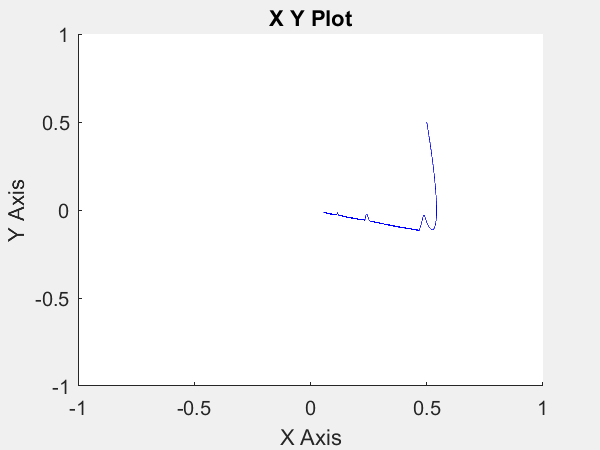

ans =   Simulink.SimulationOutput:

                   tout: [10001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


clear all
sim('Tut_Week_8_Sliding')

 Here $\left(x_1 \left(0\right),x_{2\;} \left(0\right)\right)=\left(1,1\right)$, the trajectory reaches the sliding manifold and converges to the origin evenif there is a disturbance as $2\textrm{sin2t}$. In the $\left(x,y\right)$ plane , there are two phases, reaching and sliding phases.

  Looks good. However in the sliding mode, increase the scale of the y-axis

 there are high frequency vibrations, we call this as "chattering". Moreover the control input is 

 also high frequncy vibration contained. 

   5) analyis

     The merits of sliding control is with unknown disturbance, but the maximum magnitude is known, simple to design a controller for convergence to the origin. 

    The demerits is "chattering" and control is very irregular of high frequencies. Hence the slidin mode control is not good to apply mechnical systems, especially geared system. 

  To remedy or attenuate the high frequency, there are several ways

     - use low pass filter for control input 

     - linear with a saturation 

  will be used. If you replace the sign function with a saturation, it may reduce the vibration. 

- Comment:  Slinding manifold in Linear system

Consider 

            
$$\dot{\;x} =\textrm{Ax}\;\;,x\in R^{2\;}$$


The eigenvector of $A$ are real , 

            
$${\textrm{Av}}_1 =\lambda_1 v_1 ,\;{\textrm{Av}}_{2\;} =\lambda_2 v_{2\;}$$


If the initial point $x\left(0\right)={\textrm{av}}_{1\;} ,$ then

                
$$x\left(t+\textrm{dt}\right)-x\left(t\right)=\textrm{Ax}\left(t\right)\textrm{dt}$$


-->   $x\left(\textrm{dt}\right)=\textrm{Ax}\left(0\right)+x\left(0\right)=\left(a\lambda_1 +a\right)x\left(0\right)\;\;$

-->   $x\left(t\right)={\textrm{cv}}_1 \;\;\;\;\forall \;t\ge 0$

-->   $v_1 \;$eigenvector is an sliding manifold.

- Lyapunov function re-visited

consider a stable system

               
$$\dot{\;x} =f\left(x\right)$$


Assume $V\left(x\right)\;>0,\;V\left(0\right)=0,\;\dot{\;\;V} <0$, implies

              
$$V\left(x\left(t\right)\right)\;\;\le V\left(x\left(0\right)\right)$$


imples $V\left(x\right)\;-\to V\left(0\right)=0$

Now define a manifold $s=T\left(x\right),\;T^{-1\;} \;\textrm{exists}-\to V\left(s\right)>0,$ if $\dot{V} \left(s\right)<0$

  --> $V\left(s\left(t\right)\right)<V\left(s\left(0\right)\right)$

  --> $V\left(s\left(t\right)\right)-\to V\left(s=0\right)$

  We may call $s\left(t\right)\;$to be a sliding curve. 

- Difference between state linearization/backstepping and sliding mode control

In the backstepping the systme is 

                   
$$\dot{x} =f\left(x,u\right)\;$$


here, the model is known perfectly. However  in the sliding model 

                  
$$\dot{x} =f\left(x,u\right)+g\left(x\right)\;\;,\;\left|g\left(x\right)\right|\le L$$


here $g\left(x\right)\;$ is unknown but the maximum is estimated. In this case, there is no way to cancle 

the unknown function, it is impossible to apply the state linearization including backstepping.

In this concept, in our textbook , sliding control is a robust controller. 

If the non-linearity $g\left(x\right)$ is in the sector $\left\lbrack \alpha \;\;\beta \;\right\rbrack$, luckily, if the plant is linear, the circle criterior is possible even if the $g\left(x\right)$ is unknown. 